# Ejercicios de optimización de funciones

## Encontrar un máximo o un mínimo local

7.3 Locate the minimum of the function 

*f *(*x*) = 3 + 6*x *+ 5*x^*2 + 3*x^*3 + 4*x^*4 


f=@(x) 3+6*x+5*x^2+3*x^3+4*x^4;
fu=sym(f);
[x,i,min]=nrO(f,3)

x = -0.5867

i = 8

min = logical
   1


fplot(fu,[-1 1])

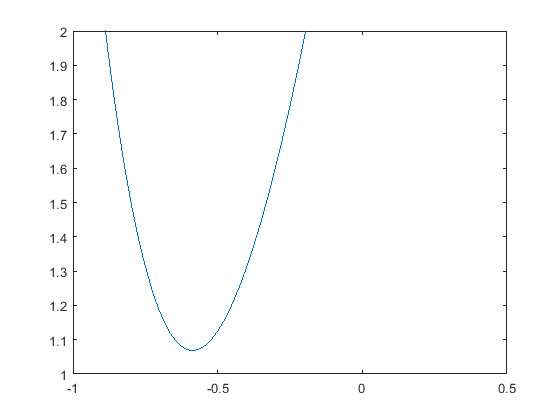

axis([-1 0.5 1 2])

xl=-1;
xu=0;
[xr,i]=proporcionAurea(f, xl,xu)

xr = -1.0980e-11

i = 52

7.2 Determine the maximum and the corresponding value of x for the function 

*f *(*x*) = −*x^*2 + 8*x *− 12 

f2=@(x)-1*(-x^2 + 8*x - 12);
fun=sym(f2);
[x,i,min]=nrO(f2,2)

x = 4

i = 1

min = logical
   1


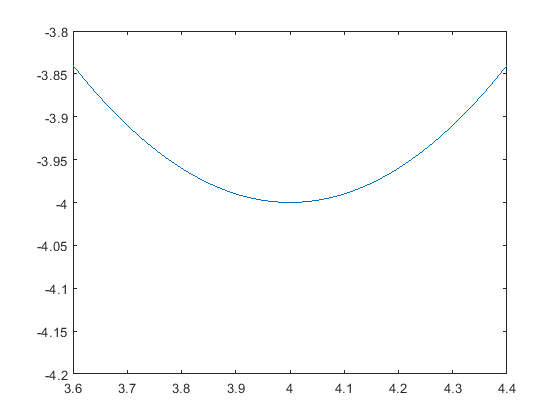

fplot(fun, [3 5])
axis([3.6 4.4 -4.2 -3.8])

7.4 Given 

*f *(*x*) = −1.5*x^*6 − 2*x^*4 + 12*x *

(a) Plot the function. 

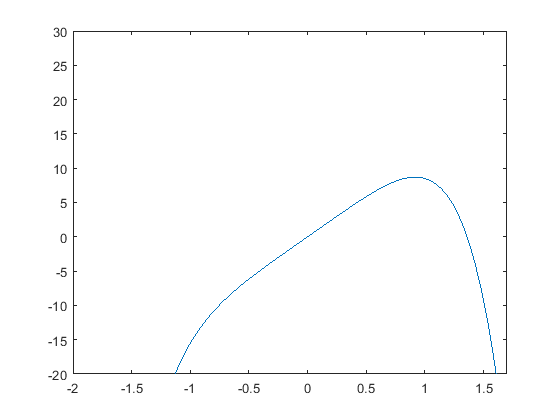

f= @(x)  -1.5*x^6 - 2*x^4 + 12*x; 
fu=sym(f);
x=[-2 2];
fplot(fu,x)
axis([-2 1.7 -20 30])

(b) Use analytical methods to prove that the function is con­cave for all values of *x*. 

(c) Find the maximum *f*(*x*) and the corre­sponding value of *x*. 

fun=sym(f);
f=-1*fun;
fun=matlabFunction(f);
[x,i,min]=nrO(fun,2)

x = 0.9169

i = 7

min = logical
   1


## Código de las funciones

Golden section search

function [xr,i]=proporcionAurea(f, xl,xu)
     t=[1 -1 -1];
     r=roots(t);
     phi=r(r>0);
     g= (phi-1);
     MAX = 52;
     tolerancia = sqrt(eps);
     i = 1;
     condicion= true;
     
     while condicion
         d=g*(xu-xl);
         x1=xl+d;
         x2=xu-d;
         xl=x2;
         i=i+1;
         condicion= (abs(xu-xl)/(abs(xu)+abs(xl)))> tolerancia  && i < MAX;
     end
     xr=(xl+xu)/2;
end


Newton optimization

function [xr,i,min]=nrO(f, xu)
%Hallar la raíz de la funcion f entre xl y xu. Empleando el método de
%Newton Rapsohd

     MAX = 52;
     tolerancia = sqrt(eps);
     i = 0;
     condicion= true;
     fx=sym(f);
     dfs1= diff(fx);
     dfs2=diff(dfs1);
     df1=matlabFunction(dfs1);
     df2=matlabFunction(dfs2);
     
     if nargin(df1)<1
         df1= @(x) df1();
     end
     if nargin(df2)<1
         df2= @(x) df2();
     end
     xr= xu-(df1(xu)/df2(xu));
     while condicion
         xu=xr;
         xr= xu-(df1(xu)/df2(xu));
         i=i+1;
         condicion= abs((xr-xu)/xr) > tolerancia  && i < MAX;
     end
     
         min= df2(xr)>0; %es mínimo

     
end